# Spectrograms extraction

Paweł Antoniuk 2021

Bialystok University of Technology

clear; clc;

## Parameters

audioBaseDirs = {'C:\data\Audio\Train\', 'C:\data\Audio\Test\'};
outputDir = 'D:\Spectrograms\';
outputBaseFilename = 'specgrams-all-lin-%d.h5';

processBatchSize = 512;
freqResolutions = [12 25 50 100 200 250];

% Get *.wav audio files in given directory
previewAudioFilenames = sort({dir(strcat(audioBaseDirs{1}, '*.wav')).name});

% Audio file info
audioInfo = audioinfo(fullfile(audioBaseDirs{1}, previewAudioFilenames{1}));
sParams.audioSampleRate = audioInfo.SampleRate;
sParams.audioDuration = audioInfo.Duration;
sParams.autioTotalSamples = audioInfo.TotalSamples;

% Spectrum-related parameters
sParams.frameDurationSeconds = 0.04;
sParams.frameHopSeconds = 0.02;
sParams.nChannels = 150;
sParams.nTimeFrames = floor(sParams.audioDuration / sParams.frameHopSeconds) - 1;
sParams.fLow = 100;
sParams.fHigh = 16000;
sParams.dbRange = 90;
sParams.nSpecgrams = 2;
sParams.specgramKey = 'pchdD';

% Window settings
sParams.windowHopSamples = round(sParams.frameHopSeconds * sParams.audioSampleRate);
sParams.windowLengthSamples = round(sParams.frameDurationSeconds * sParams.audioSampleRate);
sParams.window = hamming(sParams.windowLengthSamples);

## Draw some sample spectrograms

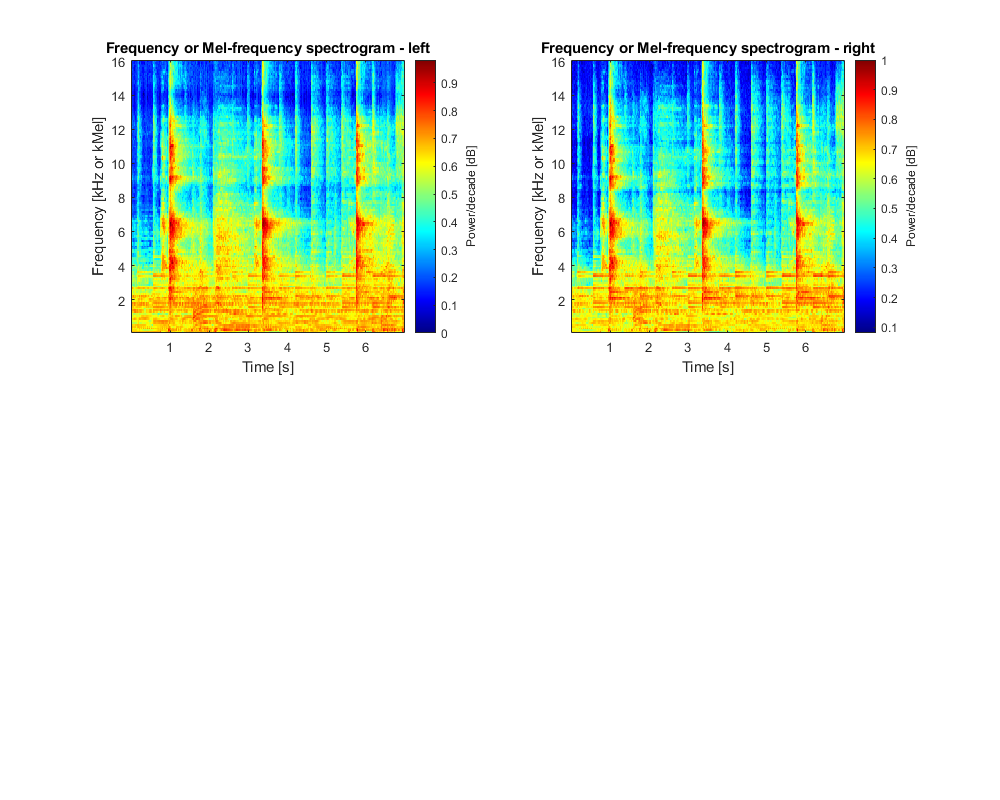

firstFilename = previewAudioFilenames{1};
[stereoSignal, sampleRate] = audioread(fullfile(audioBaseDirs{1}, firstFilename));
[timeValues, freqValues, specgrams] = createSetOfSpecgrams(stereoSignal, sParams);
specgrams = specgrams(:, :, [1 2]);
specgrams = normalizeSpecgrams(specgrams);

specNames = {'left', 'right', 'sum', 'difference'};
figure('Position', [0 0 1000 800])

for ii = 1:2
    subplot(2, 2, ii);
    imagesc(timeValues, freqValues / 1000, specgrams(:, :, ii)'); 
    colormap jet; 
    axis xy;  
    pbaspect([1 1 1])
    title(['Frequency or Mel-frequency spectrogram - ', specNames{ii}])
    xlabel('Time [s]')
    ylabel('Frequency [kHz or kMel]')
    ylabel(colorbar, 'Power/decade [dB]')
end

## Save the timeline axis and frequency axis

For each resolution...

for nChannels = freqResolutions
sParams.nChannels = nChannels;
outputFilename = fullfile(outputDir, sprintf(outputBaseFilename, nChannels));

if exist(outputFilename, 'file') == 2
    delete(outputFilename);
end

h5create(outputFilename, '/axis/time', size(timeValues));
h5create(outputFilename, '/axis/freq', size(freqValues));
h5write(outputFilename, '/axis/time', timeValues);
h5write(outputFilename, '/axis/freq', freqValues);

## Generate spectrograms

specgramSetSize = [sParams.nTimeFrames, sParams.nChannels, ...
    sParams.nSpecgrams];

nAllAudioFilenames = zeros(1, length(audioBaseDirs));
for iAudioBaseDir = 1:length(audioBaseDirs)
    audioFilenames = dir(fullfile(audioBaseDirs{iAudioBaseDir}, '*.wav'));
    nAllAudioFilenames(iAudioBaseDir) = length(audioFilenames);
end

Set datasets paths

baseDsName = '/';
dataDsName = strjoin({baseDsName, 'data'}, '/');
labelsDsName = strjoin({baseDsName, 'labels'}, '/');
filenamesDsName = strjoin({baseDsName, 'filenames'}, '/');

Create a H5 file & datasets    

h5create(outputFilename, dataDsName, [specgramSetSize, sum(nAllAudioFilenames)], ...
    'Chunksize', [specgramSetSize, 1]);
h5create(outputFilename, labelsDsName, sum(nAllAudioFilenames), ...
    'Chunksize', 1);
h5create(outputFilename, filenamesDsName, sum(nAllAudioFilenames), ...
    'ChunkSize', 1, ...
    'Datatype', 'string');

for iAudioBaseDir = 1:length(audioBaseDirs)
    tic
    nAudioFilenames = nAllAudioFilenames(iAudioBaseDir);
    baseDirOffset = sum(nAllAudioFilenames(1:iAudioBaseDir-1));

Get audio filenames

    audioBaseDir = audioBaseDirs{iAudioBaseDir}
    audioFilenames = sort({dir(fullfile(audioBaseDir, '*.wav')).name});

Save filenames

    h5write(outputFilename, filenamesDsName, audioFilenames, baseDirOffset+1, length(audioFilenames));

audioBaseDir = 'C:\data\Audio\Train\'

Data = 1×16576 string array
  Columns 1 through 399

    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClass

audioBaseDir = 'C:\data\Audio\Test\'

Data = 1×5920 string array
  Columns 1 through 399

    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceF

audioBaseDir = 'C:\data\Audio\Train\'

Data = 1×16576 string array
  Columns 1 through 399

    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClass

audioBaseDir = 'C:\data\Audio\Test\'

Data = 1×5920 string array
  Columns 1 through 399

    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceF

audioBaseDir = 'C:\data\Audio\Train\'

Data = 1×16576 string array
  Columns 1 through 399

    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClass

audioBaseDir = 'C:\data\Audio\Test\'

Data = 1×5920 string array
  Columns 1 through 399

    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceF

audioBaseDir = 'C:\data\Audio\Train\'

Data = 1×16576 string array
  Columns 1 through 399

    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClass

audioBaseDir = 'C:\data\Audio\Test\'

Data = 1×5920 string array
  Columns 1 through 399

    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceF

audioBaseDir = 'C:\data\Audio\Train\'

Data = 1×16576 string array
  Columns 1 through 399

    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClass

audioBaseDir = 'C:\data\Audio\Test\'

Data = 1×5920 string array
  Columns 1 through 399

    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceF

audioBaseDir = 'C:\data\Audio\Train\'

Data = 1×16576 string array
  Columns 1 through 399

    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClassicEducation…"    "AClass

audioBaseDir = 'C:\data\Audio\Test\'

Data = 1×5920 string array
  Columns 1 through 399

    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf1…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceForUs_hrtf2…"    "APlaceF

Generate spectrograms

    for iBatch = 1:ceil(nAudioFilenames / processBatchSize)
        fprintf('%d/%d\n', iBatch, ceil(nAudioFilenames / processBatchSize));
        
        batchFilenamesStart = (iBatch - 1) * processBatchSize + 1
        batchFilenamesEnd = min(iBatch * processBatchSize, nAudioFilenames)
        batchSize = batchFilenamesEnd - batchFilenamesStart + 1;
        batchFilenames = audioFilenames(batchFilenamesStart:batchFilenamesEnd);
        batchSpecgrams = zeros([specgramSetSize batchSize]);
        batchLabels = zeros(1, batchSize);
        
        parfor iFilename = 1:batchSize

Create and store spectrogram arrays

            filename = batchFilenames{iFilename};
            [stereoSignal, ~] = audioread(fullfile(audioBaseDir, filename));
            [~, ~, specgrams] = createSetOfSpecgrams(stereoSignal, sParams);
			specgrams = specgrams(:, :, [1 2]);
            specgrams = normalizeSpecgrams(specgrams);
            batchSpecgrams(:, :, :, iFilename) = specgrams;    

 Store label

            filenameParts = strsplit(filename, '_');
            if strcmp(filenameParts{end - 1}, 'front')
                batchLabels(iFilename) = 0;
            elseif strcmp(filenameParts{end - 1}, 'back')
                batchLabels(iFilename) = 1;
            else
                error('"%s": Name has an invalid label', filenameParts{end - 1});
            end
        end

Save spectrograms

        h5write(outputFilename, dataDsName, batchSpecgrams, [1 1 1 baseDirOffset+batchFilenamesStart], ...
            [specgramSetSize, batchSize]);   
        h5write(outputFilename, labelsDsName, batchLabels, baseDirOffset+batchFilenamesStart, batchSize);        
    end

1/33


batchFilenamesStart = 1

batchFilenamesEnd = 512

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


2/33


batchFilenamesStart = 513

batchFilenamesEnd = 1024

3/33


batchFilenamesStart = 1025

batchFilenamesEnd = 1536

4/33


batchFilenamesStart = 1537

batchFilenamesEnd = 2048

5/33


batchFilenamesStart = 2049

batchFilenamesEnd = 2560

6/33


batchFilenamesStart = 2561

batchFilenamesEnd = 3072

7/33


batchFilenamesStart = 3073

batchFilenamesEnd = 3584

8/33


batchFilenamesStart = 3585

batchFilenamesEnd = 4096

9/33


batchFilenamesStart = 4097

batchFilenamesEnd = 4608

10/33


batchFilenamesStart = 4609

batchFilenamesEnd = 5120

11/33


batchFilenamesStart = 5121

batchFilenamesEnd = 5632

12/33


batchFilenamesStart = 5633

batchFilenamesEnd = 6144

13/33


batchFilenamesStart = 6145

batchFilenamesEnd = 6656

14/33


batchFilenamesStart = 6657

batchFilenamesEnd = 7168

15/33


batchFilenamesStart = 7169

batchFilenamesEnd = 7680

16/33


batchFilenamesStart = 7681

batchFilenamesEnd = 8192

17/33


batchFilenamesStart = 8193

batchFilenamesEnd = 8704

18/33


batchFilenamesStart = 8705

batchFilenamesEnd = 9216

19/33


batchFilenamesStart = 9217

batchFilenamesEnd = 9728

20/33


batchFilenamesStart = 9729

batchFilenamesEnd = 10240

21/33


batchFilenamesStart = 10241

batchFilenamesEnd = 10752

22/33


batchFilenamesStart = 10753

batchFilenamesEnd = 11264

23/33


batchFilenamesStart = 11265

batchFilenamesEnd = 11776

24/33


batchFilenamesStart = 11777

batchFilenamesEnd = 12288

25/33


batchFilenamesStart = 12289

batchFilenamesEnd = 12800

26/33


batchFilenamesStart = 12801

batchFilenamesEnd = 13312

27/33


batchFilenamesStart = 13313

batchFilenamesEnd = 13824

28/33


batchFilenamesStart = 13825

batchFilenamesEnd = 14336

29/33


batchFilenamesStart = 14337

batchFilenamesEnd = 14848

30/33


batchFilenamesStart = 14849

batchFilenamesEnd = 15360

31/33


batchFilenamesStart = 15361

batchFilenamesEnd = 15872

32/33


batchFilenamesStart = 15873

batchFilenamesEnd = 16384

33/33


batchFilenamesStart = 16385

batchFilenamesEnd = 16576

1/12


batchFilenamesStart = 1

batchFilenamesEnd = 512

2/12


batchFilenamesStart = 513

batchFilenamesEnd = 1024

3/12


batchFilenamesStart = 1025

batchFilenamesEnd = 1536

4/12


batchFilenamesStart = 1537

batchFilenamesEnd = 2048

5/12


batchFilenamesStart = 2049

batchFilenamesEnd = 2560

6/12


batchFilenamesStart = 2561

batchFilenamesEnd = 3072

7/12


batchFilenamesStart = 3073

batchFilenamesEnd = 3584

8/12


batchFilenamesStart = 3585

batchFilenamesEnd = 4096

9/12


batchFilenamesStart = 4097

batchFilenamesEnd = 4608

10/12


batchFilenamesStart = 4609

batchFilenamesEnd = 5120

11/12


batchFilenamesStart = 5121

batchFilenamesEnd = 5632

12/12


batchFilenamesStart = 5633

batchFilenamesEnd = 5920

1/33


batchFilenamesStart = 1

batchFilenamesEnd = 512

2/33


batchFilenamesStart = 513

batchFilenamesEnd = 1024

3/33


batchFilenamesStart = 1025

batchFilenamesEnd = 1536

4/33


batchFilenamesStart = 1537

batchFilenamesEnd = 2048

5/33


batchFilenamesStart = 2049

batchFilenamesEnd = 2560

6/33


batchFilenamesStart = 2561

batchFilenamesEnd = 3072

7/33


batchFilenamesStart = 3073

batchFilenamesEnd = 3584

8/33


batchFilenamesStart = 3585

batchFilenamesEnd = 4096

9/33


batchFilenamesStart = 4097

batchFilenamesEnd = 4608

10/33


batchFilenamesStart = 4609

batchFilenamesEnd = 5120

11/33


batchFilenamesStart = 5121

batchFilenamesEnd = 5632

12/33


batchFilenamesStart = 5633

batchFilenamesEnd = 6144

13/33


batchFilenamesStart = 6145

batchFilenamesEnd = 6656

14/33


batchFilenamesStart = 6657

batchFilenamesEnd = 7168

15/33


batchFilenamesStart = 7169

batchFilenamesEnd = 7680

16/33


batchFilenamesStart = 7681

batchFilenamesEnd = 8192

17/33


batchFilenamesStart = 8193

batchFilenamesEnd = 8704

18/33


batchFilenamesStart = 8705

batchFilenamesEnd = 9216

19/33


batchFilenamesStart = 9217

batchFilenamesEnd = 9728

20/33


batchFilenamesStart = 9729

batchFilenamesEnd = 10240

21/33


batchFilenamesStart = 10241

batchFilenamesEnd = 10752

22/33


batchFilenamesStart = 10753

batchFilenamesEnd = 11264

23/33


batchFilenamesStart = 11265

batchFilenamesEnd = 11776

24/33


batchFilenamesStart = 11777

batchFilenamesEnd = 12288

25/33


batchFilenamesStart = 12289

batchFilenamesEnd = 12800

26/33


batchFilenamesStart = 12801

batchFilenamesEnd = 13312

27/33


batchFilenamesStart = 13313

batchFilenamesEnd = 13824

28/33


batchFilenamesStart = 13825

batchFilenamesEnd = 14336

29/33


batchFilenamesStart = 14337

batchFilenamesEnd = 14848

30/33


batchFilenamesStart = 14849

batchFilenamesEnd = 15360

31/33


batchFilenamesStart = 15361

batchFilenamesEnd = 15872

32/33


batchFilenamesStart = 15873

batchFilenamesEnd = 16384

33/33


batchFilenamesStart = 16385

batchFilenamesEnd = 16576

1/12


batchFilenamesStart = 1

batchFilenamesEnd = 512

2/12


batchFilenamesStart = 513

batchFilenamesEnd = 1024

3/12


batchFilenamesStart = 1025

batchFilenamesEnd = 1536

4/12


batchFilenamesStart = 1537

batchFilenamesEnd = 2048

5/12


batchFilenamesStart = 2049

batchFilenamesEnd = 2560

6/12


batchFilenamesStart = 2561

batchFilenamesEnd = 3072

7/12


batchFilenamesStart = 3073

batchFilenamesEnd = 3584

8/12


batchFilenamesStart = 3585

batchFilenamesEnd = 4096

9/12


batchFilenamesStart = 4097

batchFilenamesEnd = 4608

10/12


batchFilenamesStart = 4609

batchFilenamesEnd = 5120

11/12


batchFilenamesStart = 5121

batchFilenamesEnd = 5632

12/12


batchFilenamesStart = 5633

batchFilenamesEnd = 5920

1/33


batchFilenamesStart = 1

batchFilenamesEnd = 512

2/33


batchFilenamesStart = 513

batchFilenamesEnd = 1024

3/33


batchFilenamesStart = 1025

batchFilenamesEnd = 1536

4/33


batchFilenamesStart = 1537

batchFilenamesEnd = 2048

5/33


batchFilenamesStart = 2049

batchFilenamesEnd = 2560

6/33


batchFilenamesStart = 2561

batchFilenamesEnd = 3072

7/33


batchFilenamesStart = 3073

batchFilenamesEnd = 3584

8/33


batchFilenamesStart = 3585

batchFilenamesEnd = 4096

9/33


batchFilenamesStart = 4097

batchFilenamesEnd = 4608

10/33


batchFilenamesStart = 4609

batchFilenamesEnd = 5120

11/33


batchFilenamesStart = 5121

batchFilenamesEnd = 5632

12/33


batchFilenamesStart = 5633

batchFilenamesEnd = 6144

13/33


batchFilenamesStart = 6145

batchFilenamesEnd = 6656

14/33


batchFilenamesStart = 6657

batchFilenamesEnd = 7168

15/33


batchFilenamesStart = 7169

batchFilenamesEnd = 7680

16/33


batchFilenamesStart = 7681

batchFilenamesEnd = 8192

17/33


batchFilenamesStart = 8193

batchFilenamesEnd = 8704

18/33


batchFilenamesStart = 8705

batchFilenamesEnd = 9216

19/33


batchFilenamesStart = 9217

batchFilenamesEnd = 9728

20/33


batchFilenamesStart = 9729

batchFilenamesEnd = 10240

21/33


batchFilenamesStart = 10241

batchFilenamesEnd = 10752

22/33


batchFilenamesStart = 10753

batchFilenamesEnd = 11264

23/33


batchFilenamesStart = 11265

batchFilenamesEnd = 11776

24/33


batchFilenamesStart = 11777

batchFilenamesEnd = 12288

25/33


batchFilenamesStart = 12289

batchFilenamesEnd = 12800

26/33


batchFilenamesStart = 12801

batchFilenamesEnd = 13312

27/33


batchFilenamesStart = 13313

batchFilenamesEnd = 13824

28/33


batchFilenamesStart = 13825

batchFilenamesEnd = 14336

29/33


batchFilenamesStart = 14337

batchFilenamesEnd = 14848

30/33


batchFilenamesStart = 14849

batchFilenamesEnd = 15360

31/33


batchFilenamesStart = 15361

batchFilenamesEnd = 15872

32/33


batchFilenamesStart = 15873

batchFilenamesEnd = 16384

33/33


batchFilenamesStart = 16385

batchFilenamesEnd = 16576

1/12


batchFilenamesStart = 1

batchFilenamesEnd = 512

2/12


batchFilenamesStart = 513

batchFilenamesEnd = 1024

3/12


batchFilenamesStart = 1025

batchFilenamesEnd = 1536

4/12


batchFilenamesStart = 1537

batchFilenamesEnd = 2048

5/12


batchFilenamesStart = 2049

batchFilenamesEnd = 2560

6/12


batchFilenamesStart = 2561

batchFilenamesEnd = 3072

7/12


batchFilenamesStart = 3073

batchFilenamesEnd = 3584

8/12


batchFilenamesStart = 3585

batchFilenamesEnd = 4096

9/12


batchFilenamesStart = 4097

batchFilenamesEnd = 4608

10/12


batchFilenamesStart = 4609

batchFilenamesEnd = 5120

11/12


batchFilenamesStart = 5121

batchFilenamesEnd = 5632

12/12


batchFilenamesStart = 5633

batchFilenamesEnd = 5920

1/33


batchFilenamesStart = 1

batchFilenamesEnd = 512

2/33


batchFilenamesStart = 513

batchFilenamesEnd = 1024

3/33


batchFilenamesStart = 1025

batchFilenamesEnd = 1536

4/33


batchFilenamesStart = 1537

batchFilenamesEnd = 2048

5/33


batchFilenamesStart = 2049

batchFilenamesEnd = 2560

6/33


batchFilenamesStart = 2561

batchFilenamesEnd = 3072

7/33


batchFilenamesStart = 3073

batchFilenamesEnd = 3584

8/33


batchFilenamesStart = 3585

batchFilenamesEnd = 4096

9/33


batchFilenamesStart = 4097

batchFilenamesEnd = 4608

10/33


batchFilenamesStart = 4609

batchFilenamesEnd = 5120

11/33


batchFilenamesStart = 5121

batchFilenamesEnd = 5632

12/33


batchFilenamesStart = 5633

batchFilenamesEnd = 6144

13/33


batchFilenamesStart = 6145

batchFilenamesEnd = 6656

14/33


batchFilenamesStart = 6657

batchFilenamesEnd = 7168

15/33


batchFilenamesStart = 7169

batchFilenamesEnd = 7680

16/33


batchFilenamesStart = 7681

batchFilenamesEnd = 8192

17/33


batchFilenamesStart = 8193

batchFilenamesEnd = 8704

18/33


batchFilenamesStart = 8705

batchFilenamesEnd = 9216

19/33


batchFilenamesStart = 9217

batchFilenamesEnd = 9728

20/33


batchFilenamesStart = 9729

batchFilenamesEnd = 10240

21/33


batchFilenamesStart = 10241

batchFilenamesEnd = 10752

22/33


batchFilenamesStart = 10753

batchFilenamesEnd = 11264

23/33


batchFilenamesStart = 11265

batchFilenamesEnd = 11776

24/33


batchFilenamesStart = 11777

batchFilenamesEnd = 12288

25/33


batchFilenamesStart = 12289

batchFilenamesEnd = 12800

26/33


batchFilenamesStart = 12801

batchFilenamesEnd = 13312

27/33


batchFilenamesStart = 13313

batchFilenamesEnd = 13824

28/33


batchFilenamesStart = 13825

batchFilenamesEnd = 14336

29/33


batchFilenamesStart = 14337

batchFilenamesEnd = 14848

30/33


batchFilenamesStart = 14849

batchFilenamesEnd = 15360

31/33


batchFilenamesStart = 15361

batchFilenamesEnd = 15872

32/33


batchFilenamesStart = 15873

batchFilenamesEnd = 16384

33/33


batchFilenamesStart = 16385

batchFilenamesEnd = 16576

1/12


batchFilenamesStart = 1

batchFilenamesEnd = 512

2/12


batchFilenamesStart = 513

batchFilenamesEnd = 1024

3/12


batchFilenamesStart = 1025

batchFilenamesEnd = 1536

4/12


batchFilenamesStart = 1537

batchFilenamesEnd = 2048

5/12


batchFilenamesStart = 2049

batchFilenamesEnd = 2560

6/12


batchFilenamesStart = 2561

batchFilenamesEnd = 3072

7/12


batchFilenamesStart = 3073

batchFilenamesEnd = 3584

8/12


batchFilenamesStart = 3585

batchFilenamesEnd = 4096

9/12


batchFilenamesStart = 4097

batchFilenamesEnd = 4608

10/12


batchFilenamesStart = 4609

batchFilenamesEnd = 5120

11/12


batchFilenamesStart = 5121

batchFilenamesEnd = 5632

12/12


batchFilenamesStart = 5633

batchFilenamesEnd = 5920

1/33


batchFilenamesStart = 1

batchFilenamesEnd = 512

2/33


batchFilenamesStart = 513

batchFilenamesEnd = 1024

3/33


batchFilenamesStart = 1025

batchFilenamesEnd = 1536

4/33


batchFilenamesStart = 1537

batchFilenamesEnd = 2048

5/33


batchFilenamesStart = 2049

batchFilenamesEnd = 2560

6/33


batchFilenamesStart = 2561

batchFilenamesEnd = 3072

7/33


batchFilenamesStart = 3073

batchFilenamesEnd = 3584

8/33


batchFilenamesStart = 3585

batchFilenamesEnd = 4096

9/33


batchFilenamesStart = 4097

batchFilenamesEnd = 4608

10/33


batchFilenamesStart = 4609

batchFilenamesEnd = 5120

11/33


batchFilenamesStart = 5121

batchFilenamesEnd = 5632

12/33


batchFilenamesStart = 5633

batchFilenamesEnd = 6144

13/33


batchFilenamesStart = 6145

batchFilenamesEnd = 6656

14/33


batchFilenamesStart = 6657

batchFilenamesEnd = 7168

15/33


batchFilenamesStart = 7169

batchFilenamesEnd = 7680

16/33


batchFilenamesStart = 7681

batchFilenamesEnd = 8192

17/33


batchFilenamesStart = 8193

batchFilenamesEnd = 8704

18/33


batchFilenamesStart = 8705

batchFilenamesEnd = 9216

19/33


batchFilenamesStart = 9217

batchFilenamesEnd = 9728

20/33


batchFilenamesStart = 9729

batchFilenamesEnd = 10240

21/33


batchFilenamesStart = 10241

batchFilenamesEnd = 10752

22/33


batchFilenamesStart = 10753

batchFilenamesEnd = 11264

23/33


batchFilenamesStart = 11265

batchFilenamesEnd = 11776

24/33


batchFilenamesStart = 11777

batchFilenamesEnd = 12288

25/33


batchFilenamesStart = 12289

batchFilenamesEnd = 12800

26/33


batchFilenamesStart = 12801

batchFilenamesEnd = 13312

27/33


batchFilenamesStart = 13313

batchFilenamesEnd = 13824

28/33


batchFilenamesStart = 13825

batchFilenamesEnd = 14336

29/33


batchFilenamesStart = 14337

batchFilenamesEnd = 14848

30/33


batchFilenamesStart = 14849

batchFilenamesEnd = 15360

31/33


batchFilenamesStart = 15361

batchFilenamesEnd = 15872

32/33


batchFilenamesStart = 15873

batchFilenamesEnd = 16384

33/33


batchFilenamesStart = 16385

batchFilenamesEnd = 16576

1/12


batchFilenamesStart = 1

batchFilenamesEnd = 512

2/12


batchFilenamesStart = 513

batchFilenamesEnd = 1024

3/12


batchFilenamesStart = 1025

batchFilenamesEnd = 1536

4/12


batchFilenamesStart = 1537

batchFilenamesEnd = 2048

5/12


batchFilenamesStart = 2049

batchFilenamesEnd = 2560

6/12


batchFilenamesStart = 2561

batchFilenamesEnd = 3072

7/12


batchFilenamesStart = 3073

batchFilenamesEnd = 3584

8/12


batchFilenamesStart = 3585

batchFilenamesEnd = 4096

9/12


batchFilenamesStart = 4097

batchFilenamesEnd = 4608

10/12


batchFilenamesStart = 4609

batchFilenamesEnd = 5120

11/12


batchFilenamesStart = 5121

batchFilenamesEnd = 5632

12/12


batchFilenamesStart = 5633

batchFilenamesEnd = 5920

1/33


batchFilenamesStart = 1

batchFilenamesEnd = 512

2/33


batchFilenamesStart = 513

batchFilenamesEnd = 1024

3/33


batchFilenamesStart = 1025

batchFilenamesEnd = 1536

4/33


batchFilenamesStart = 1537

batchFilenamesEnd = 2048

5/33


batchFilenamesStart = 2049

batchFilenamesEnd = 2560

6/33


batchFilenamesStart = 2561

batchFilenamesEnd = 3072

7/33


batchFilenamesStart = 3073

batchFilenamesEnd = 3584

8/33


batchFilenamesStart = 3585

batchFilenamesEnd = 4096

9/33


batchFilenamesStart = 4097

batchFilenamesEnd = 4608

10/33


batchFilenamesStart = 4609

batchFilenamesEnd = 5120

11/33


batchFilenamesStart = 5121

batchFilenamesEnd = 5632

12/33


batchFilenamesStart = 5633

batchFilenamesEnd = 6144

13/33


batchFilenamesStart = 6145

batchFilenamesEnd = 6656

14/33


batchFilenamesStart = 6657

batchFilenamesEnd = 7168

15/33


batchFilenamesStart = 7169

batchFilenamesEnd = 7680

16/33


batchFilenamesStart = 7681

batchFilenamesEnd = 8192

17/33


batchFilenamesStart = 8193

batchFilenamesEnd = 8704

18/33


batchFilenamesStart = 8705

batchFilenamesEnd = 9216

19/33


batchFilenamesStart = 9217

batchFilenamesEnd = 9728

20/33


batchFilenamesStart = 9729

batchFilenamesEnd = 10240

21/33


batchFilenamesStart = 10241

batchFilenamesEnd = 10752

22/33


batchFilenamesStart = 10753

batchFilenamesEnd = 11264

23/33


batchFilenamesStart = 11265

batchFilenamesEnd = 11776

24/33


batchFilenamesStart = 11777

batchFilenamesEnd = 12288

25/33


batchFilenamesStart = 12289

batchFilenamesEnd = 12800

26/33


batchFilenamesStart = 12801

batchFilenamesEnd = 13312

27/33


batchFilenamesStart = 13313

batchFilenamesEnd = 13824

28/33


batchFilenamesStart = 13825

batchFilenamesEnd = 14336

29/33


batchFilenamesStart = 14337

batchFilenamesEnd = 14848

30/33


batchFilenamesStart = 14849

batchFilenamesEnd = 15360

31/33


batchFilenamesStart = 15361

batchFilenamesEnd = 15872

32/33


batchFilenamesStart = 15873

batchFilenamesEnd = 16384

33/33


batchFilenamesStart = 16385

batchFilenamesEnd = 16576

1/12


batchFilenamesStart = 1

batchFilenamesEnd = 512

2/12


batchFilenamesStart = 513

batchFilenamesEnd = 1024

3/12


batchFilenamesStart = 1025

batchFilenamesEnd = 1536

4/12


batchFilenamesStart = 1537

batchFilenamesEnd = 2048

5/12


batchFilenamesStart = 2049

batchFilenamesEnd = 2560

6/12


batchFilenamesStart = 2561

batchFilenamesEnd = 3072

7/12


batchFilenamesStart = 3073

batchFilenamesEnd = 3584

8/12


batchFilenamesStart = 3585

batchFilenamesEnd = 4096

9/12


batchFilenamesStart = 4097

batchFilenamesEnd = 4608

10/12


batchFilenamesStart = 4609

batchFilenamesEnd = 5120

11/12


batchFilenamesStart = 5121

batchFilenamesEnd = 5632

12/12


batchFilenamesStart = 5633

batchFilenamesEnd = 5920

    
    toc

Elapsed time is 1278.671460 seconds.


Elapsed time is 409.620900 seconds.


Elapsed time is 1303.648861 seconds.


Elapsed time is 465.942614 seconds.


Elapsed time is 1301.908763 seconds.


Elapsed time is 542.656658 seconds.


Elapsed time is 1327.582297 seconds.


Elapsed time is 514.702747 seconds.


Elapsed time is 1609.344474 seconds.


Elapsed time is 578.857053 seconds.


Elapsed time is 1609.431276 seconds.


Elapsed time is 560.383621 seconds.


end
end